# Analisi della significatività dei picchi

clear all
load Dati/sst_nino3_m.dat;
load Dati/time_nino3_m.dat;

[nino_mean nino_sigma] = normfit(sst_nino3_m);
nino_serie = normalize(sst_nino3_m,'zscore');

nfft = 2048;
f_s = 12; % anni^(-1)

[Pxx, f] = periodogram(nino_serie, [], nfft, f_s, 'twosided'); % Le parentesi quadre indicano la finestra rettangolare
Pxx = Pxx*f_s; % Normalizzazione spettrale

[B,I] = maxk(Pxx(1:nfft/2+1),4000);
B(2) = [];
I(2) = [];
% Periodi
period = 1./f;

% Significatività
fac_signif95 = chi2inv(.95, 2)/2; % 95% di significatività
fac_signif99 = chi2inv(.999, 2)/2; % 99.9% di significatività

## Significatività 

% Livello di significatività per rumore bianco
% La varianza deve essere unitaria in quanto si è normalizzato il periodogramma per la deviazione standard
Pbianco = ones(1, length(Pxx));
signif95 = fac_signif95*Pbianco;
signif99 = fac_signif99*Pbianco;

%I = f(Pxx(2:nfft/2+1)>fac_signif99);
%B = Pxx(Pxx(2:nfft/2+1)>fac_signif99);

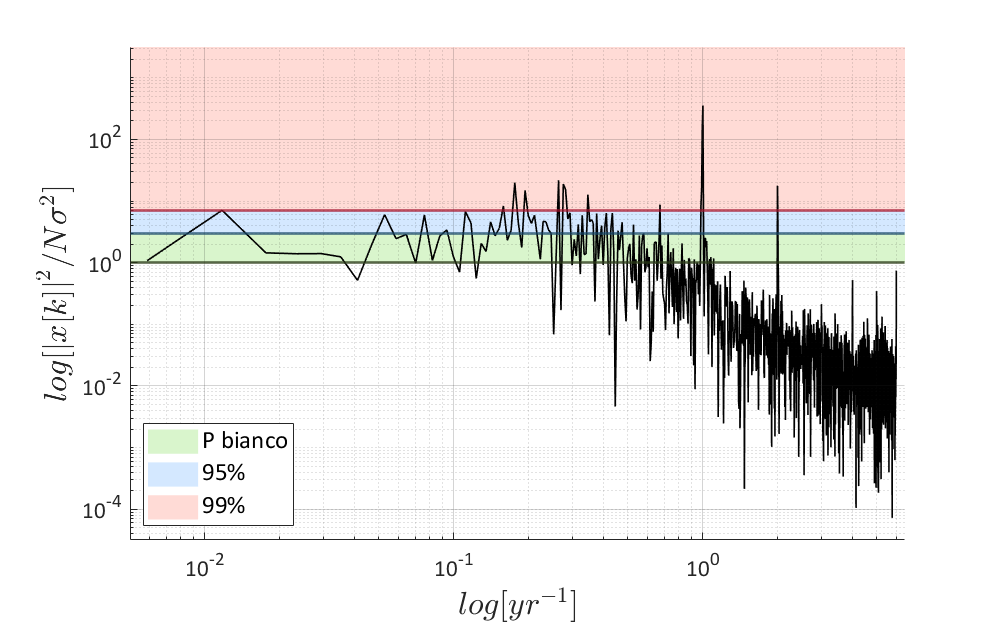


f1 = figure;
f1.Position = [90 90 800 500];

loglog(f(2:nfft/2+1), Pxx(2:nfft/2+1), 'color','k', 'LineWidth', 1, 'HandleVisibility','off')
hold on
patch([0.005 6.5 6.5 0.005],[1 1 10000 10000],[0.85 0.96 0.8],'EdgeColor','none', 'DisplayName', 'P bianco')
hold on
patch([0.005 6.5 6.5 0.005],[fac_signif95 fac_signif95 10000 10000],[0.83 0.91 1],'EdgeColor','none', 'DisplayName', '95%')
hold on
patch([0.005 6.5 6.5 0.005],[fac_signif99 fac_signif99 10000 10000],[1 0.86 0.84],'EdgeColor','none', 'DisplayName', '99%')
hold on
loglog(f(2:nfft/2+1), Pxx(2:nfft/2+1),'-', 'color','k', 'LineWidth', 1, 'HandleVisibility','off')
hold on 
yline(1,'LineWidth',1.7,'Color',[0.17 0.23 0.09], 'HandleVisibility','off');
hold on
yline(fac_signif99,'LineWidth',1.7,'Color',[0.64 0.08 0.18], 'HandleVisibility','off');
hold on
yline(fac_signif95,'LineWidth',1.7,'Color',[0.09 0.28 0.41], 'HandleVisibility','off');
set(gca,'FontSize',14,'FontName','Calibri');
set(gca, 'YLim', [10^(-4.5) 10^(3.5)])
set(gca, 'XLim', [0.005 6.5])
xlabel('$log[yr^{-1}]$', 'Interpreter','latex','FontSize',19,'FontName','Calibri')
ylabel('$log[{|x[k]|}^2/N\sigma^2]$', 'Interpreter','latex','FontSize',19,'FontName','Calibri')

% Grid Settings
grid on
ax=gca;
ax.Layer = 'top';
ax.GridAlpha = 0.2;
hold off
set(gca,'box','off')
legend('FontSize',15,'Orientation','vertical','Location','southwest');

print('Grafici/periodogram_sign_bianco','-dpng')

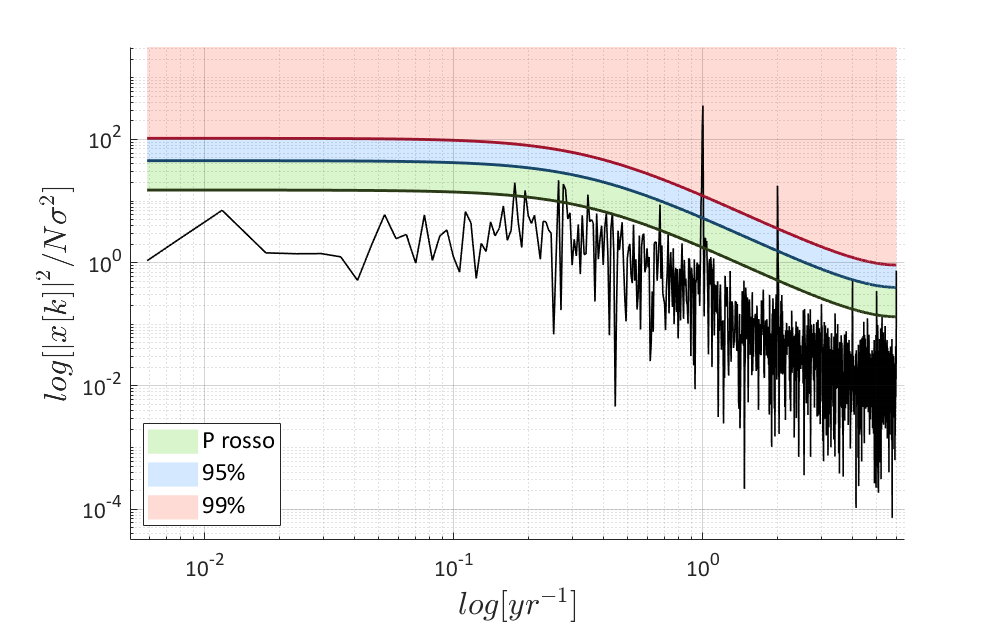


f2 = figure;
f2.Position = [90 90 800 500];

[Prosso, nurosso] = redbckg(sst_nino3_m, nfft);
signif95 = fac_signif95*Prosso;
signif99 = fac_signif99*Prosso;
period_rosso = 1./(nurosso*f_s);

loglog(f(2:nfft/2+1), Pxx(2:nfft/2+1), 'color','k', 'LineWidth', 1, 'HandleVisibility','off')
hold on
for i=1:(nfft/2)-1
    patch([f(i) f(i+1) f(i+1) f(i)], [Prosso(i) Prosso(i+1) 10000 10000],[0.85 0.96 0.8],'EdgeColor','none','HandleVisibility','off')
    hold on
    patch([f(i) f(i+1) f(i+1) f(i)], [signif95(i) signif95(i+1) 10000 10000],[0.83 0.91 1],'EdgeColor','none','HandleVisibility','off')
    hold on
    patch([f(i) f(i+1) f(i+1) f(i)], [signif99(i) signif99(i+1) 10000 10000],[1 0.86 0.84],'EdgeColor','none','HandleVisibility','off')
    hold on
end
patch([f(nfft/2) f(nfft/2+1) f(nfft/2+1) f(nfft/2)], [Prosso(nfft/2) Prosso(nfft/2+1) 10000 10000],[0.85 0.96 0.8],'EdgeColor','none', 'DisplayName', 'P rosso')
hold on
patch([f(nfft/2) f(nfft/2+1) f(nfft/2+1) f(nfft/2)], [signif95(nfft/2) signif95(nfft/2+1) 10000 10000],[0.83 0.91 1],'EdgeColor','none', 'DisplayName', '95%')
hold on
patch([f(nfft/2) f(nfft/2+1) f(nfft/2+1) f(nfft/2)], [signif99(nfft/2) signif99(nfft/2+1) 10000 10000],[1 0.86 0.84],'EdgeColor','none', 'DisplayName', '99%')
hold on
loglog(f(2:nfft/2+1), Pxx(2:nfft/2+1),'-', 'color','k', 'LineWidth', 1, 'HandleVisibility','off')
hold on
plot(f(2:nfft/2+1), Prosso(2:nfft/2+1),'-','LineWidth',1.7,'Color',[0.17 0.23 0.09], 'HandleVisibility','off');
hold on
plot(f(2:nfft/2+1), signif95(2:nfft/2+1),'-','LineWidth',1.7,'Color',[0.09 0.28 0.41], 'HandleVisibility','off');
hold on
plot(f(2:nfft/2+1), signif99(2:nfft/2+1),'-','LineWidth',1.7,'Color',[0.64 0.08 0.18], 'HandleVisibility','off');
set(gca,'FontSize',14,'FontName','Calibri');
set(gca, 'YLim', [10^(-4.5) 10^(3.5)])
set(gca, 'XLim', [0.005 6.5])
xlabel('$log[yr^{-1}]$', 'Interpreter','latex','FontSize',19,'FontName','Calibri')
ylabel('$log[{|x[k]|}^2/N\sigma^2]$', 'Interpreter','latex','FontSize',19,'FontName','Calibri')

% Grid Settings
grid on
ax=gca;
ax.Layer = 'top';
ax.GridAlpha = 0.2;
hold off
set(gca,'box','off')

legend('FontSize',15,'Orientation','vertical','Location','southwest');

print('Grafici/periodogram_sign_rosso','-dpng')

massimi = [period(I) B zeros(1024,1) zeros(1024,1) zeros(1024,1) zeros(1024,1)];
%massimi = sortrows(massimi,2);
massimi(:,3) = massimi(:,2)>fac_signif95;
massimi(:,4) = massimi(:,2)>fac_signif99;
for i = 1:1024
    if massimi(i,2)> signif95(I(i))
        massimi(i,5) = 1;
    end
    if massimi(i,2)> signif99(I(i))
        massimi(i,6) = 1;
    end
end
massimi = sortrows(massimi,5);

for i = 1:1024
    massimi(i,7) = (1/((1/massimi(i,1))-0.0059)-1/((1/massimi(i,1))+0.0059))*365;
end

clear all
load Dati/a_sst_nino3_m.dat;
load Dati/time_nino3_m.dat;

sst_nino3_m = a_sst_nino3_m;

[nino_mean nino_sigma] = normfit(sst_nino3_m);
nino_serie = normalize(sst_nino3_m,'zscore');

nfft = 2048;
f_s = 12; % anni^(-1)

[Pxx, f] = periodogram(nino_serie, [], nfft, f_s, 'twosided'); % Le parentesi quadre indicano la finestra rettangolare
Pxx = Pxx*f_s; % Normalizzazione spettrale

[B,I] = maxk(Pxx(1:nfft/2+1),40);
B(2) = [];
I(2) = [];
% Periodi
period = 1./f;

% Significatività
fac_signif95 = chi2inv(.95, 2)/2; % 95% di significatività
fac_signif99 = chi2inv(.999, 2)/2; % 99.9% di significatività

# Analisi della significatività dei picchi - Whitening

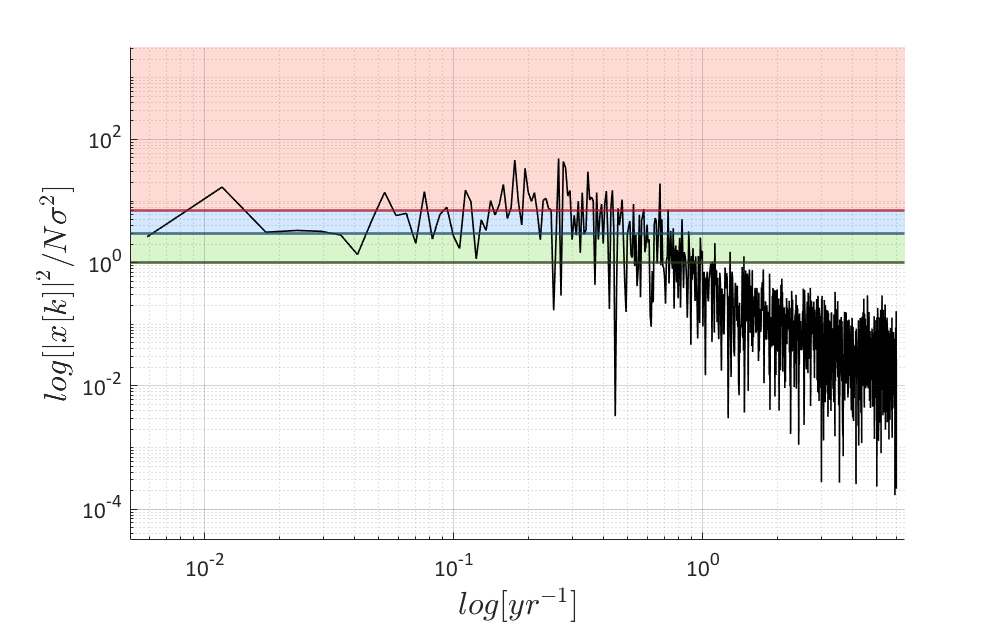

% Livello di significatività per rumore bianco
% La varianza deve essere unitaria in quanto si è normalizzato il periodogramma per la deviazione standard
Pbianco = ones(1, length(Pxx));
signif95 = fac_signif95*Pbianco;
signif99 = fac_signif99*Pbianco;

%I = f(Pxx(2:nfft/2+1)>fac_signif99);
%B = Pxx(Pxx(2:nfft/2+1)>fac_signif99);

f3 = figure;
f3.Position = [90 90 800 500];

loglog(f(2:nfft/2+1), Pxx(2:nfft/2+1), 'color','k', 'LineWidth', 1, 'HandleVisibility','off')
hold on
patch([0.005 6.5 6.5 0.005],[1 1 10000 10000],[0.85 0.96 0.8],'EdgeColor','none', 'DisplayName', 'P bianco')
hold on
patch([0.005 6.5 6.5 0.005],[fac_signif95 fac_signif95 10000 10000],[0.83 0.91 1],'EdgeColor','none', 'DisplayName', '95%')
hold on
patch([0.005 6.5 6.5 0.005],[fac_signif99 fac_signif99 10000 10000],[1 0.86 0.84],'EdgeColor','none', 'DisplayName', '99%')
hold on
loglog(f(2:nfft/2+1), Pxx(2:nfft/2+1),'-', 'color','k', 'LineWidth', 1, 'HandleVisibility','off')
hold on 
yline(1,'LineWidth',1.7,'Color',[0.17 0.23 0.09], 'HandleVisibility','off');
hold on
yline(fac_signif99,'LineWidth',1.7,'Color',[0.64 0.08 0.18], 'HandleVisibility','off');
hold on
yline(fac_signif95,'LineWidth',1.7,'Color',[0.09 0.28 0.41], 'HandleVisibility','off');
set(gca,'FontSize',14,'FontName','Calibri');
set(gca, 'YLim', [10^(-4.5) 10^(3.5)])
set(gca, 'XLim', [0.005 6.5])
xlabel('$log[yr^{-1}]$', 'Interpreter','latex','FontSize',19,'FontName','Calibri')
ylabel('$log[{|x[k]|}^2/N\sigma^2]$', 'Interpreter','latex','FontSize',19,'FontName','Calibri')

% Grid Settings
grid on
ax=gca;
ax.Layer = 'top';
ax.GridAlpha = 0.2;
hold off
set(gca,'box','off')

print('Grafici/periodogram_sign_bianco_wht','-dpng')

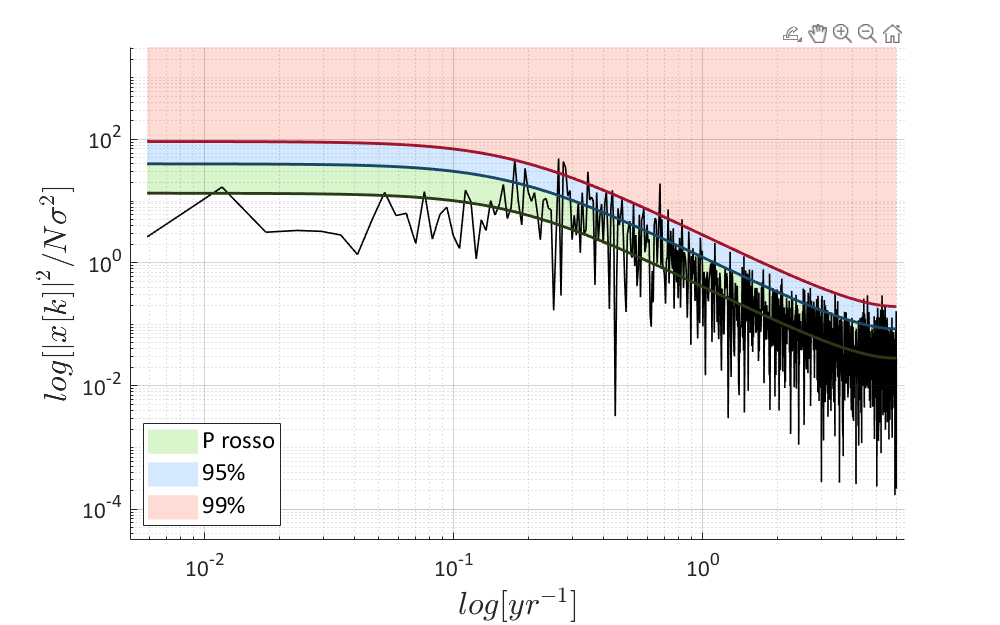


[Prosso, nurosso] = redbckg(sst_nino3_m, nfft);
signif95 = fac_signif95*Prosso;
signif99 = fac_signif99*Prosso;
period_rosso = 1./(nurosso*f_s);

f4 = figure;
f4.Position = [90 90 800 500];

loglog(f(2:nfft/2+1), Pxx(2:nfft/2+1), 'color','k', 'LineWidth', 1, 'HandleVisibility','off')
hold on
for i=1:(nfft/2)-1
    patch([f(i) f(i+1) f(i+1) f(i)], [Prosso(i) Prosso(i+1) 10000 10000],[0.85 0.96 0.8],'EdgeColor','none','HandleVisibility','off')
    hold on
    patch([f(i) f(i+1) f(i+1) f(i)], [signif95(i) signif95(i+1) 10000 10000],[0.83 0.91 1],'EdgeColor','none','HandleVisibility','off')
    hold on
    patch([f(i) f(i+1) f(i+1) f(i)], [signif99(i) signif99(i+1) 10000 10000],[1 0.86 0.84],'EdgeColor','none','HandleVisibility','off')
    hold on
end
patch([f(nfft/2) f(nfft/2+1) f(nfft/2+1) f(nfft/2)], [Prosso(nfft/2) Prosso(nfft/2+1) 10000 10000],[0.85 0.96 0.8],'EdgeColor','none', 'DisplayName', 'P rosso')
hold on
patch([f(nfft/2) f(nfft/2+1) f(nfft/2+1) f(nfft/2)], [signif95(nfft/2) signif95(nfft/2+1) 10000 10000],[0.83 0.91 1],'EdgeColor','none', 'DisplayName', '95%')
hold on
patch([f(nfft/2) f(nfft/2+1) f(nfft/2+1) f(nfft/2)], [signif99(nfft/2) signif99(nfft/2+1) 10000 10000],[1 0.86 0.84],'EdgeColor','none', 'DisplayName', '99%')
hold on
loglog(f(2:nfft/2+1), Pxx(2:nfft/2+1),'-', 'color','k', 'LineWidth', 1, 'HandleVisibility','off')
hold on
plot(f(2:nfft/2+1), Prosso(2:nfft/2+1),'-','LineWidth',1.7,'Color',[0.17 0.23 0.09], 'HandleVisibility','off');
hold on
plot(f(2:nfft/2+1), signif95(2:nfft/2+1),'-','LineWidth',1.7,'Color',[0.09 0.28 0.41], 'HandleVisibility','off');
hold on
plot(f(2:nfft/2+1), signif99(2:nfft/2+1),'-','LineWidth',1.7,'Color',[0.64 0.08 0.18], 'HandleVisibility','off');
set(gca,'FontSize',14,'FontName','Calibri');
set(gca, 'YLim', [10^(-4.5) 10^(3.5)])
set(gca, 'XLim', [0.005 6.5])
xlabel('$log[yr^{-1}]$', 'Interpreter','latex','FontSize',19,'FontName','Calibri')
ylabel('$log[{|x[k]|}^2/N\sigma^2]$', 'Interpreter','latex','FontSize',19,'FontName','Calibri')


% Grid Settings
grid on
ax=gca;
ax.Layer = 'top';
ax.GridAlpha = 0.2;
hold off
set(gca,'box','off')

legend('FontSize',15,'Orientation','vertical','Location','southwest');

print('Grafici/periodogram_sign_rosso_wht','-dpng')

massimi = [period(I) B zeros(39,1) zeros(39,1) zeros(39,1) zeros(39,1) zeros(39,1)];
massimi = sortrows(massimi,2);
massimi(:,3) = massimi(:,2)>fac_signif95;
massimi(:,4) = massimi(:,2)>fac_signif99;
for i = 1:39
    if massimi(i,2)> signif95(I(i))
        massimi(i,5) = 1;
    end
    if massimi(i,2)> signif99(I(i))
        massimi(i,6) = 1;
    end
end
%massimi = sortrows(massimi,1);

for i = 1:39
    massimi(i,7) = ((1/(massimi(i,1)-0.0059)-1/(massimi(i,1)+0.0059)));
end